addpath("TensorLab20");

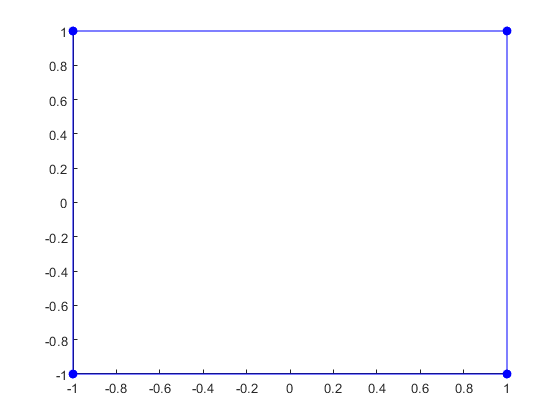

ans =   Patch with properties:

    FaceColor: 'none'
    FaceAlpha: 1
    EdgeColor: [0 0 1]
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  Show all properties


e = cartesianbasis2d("e1", "e2");
e1 = e(1);
e2 = e(2);
xie = [ -e1 - e2
e1 - e2
e1 + e2
-e1 + e2 ];
Q = [ 1 2 3 4 ];
femplot(xie, Q, 'Nodes', 'on')

xi = 1*e1 + 1*e2

xi =

    1.0000*e1 + 1.0000*e2



xi1 = dot(xi, e1);
xi2 = dot(xi, e2);
Ne = [ 1/4*(1-xi1)*(1-xi2)
1/4*(1+xi1)*(1-xi2)
1/4*(1+xi1)*(1+xi2)
1/4*(1-xi1)*(1+xi2) ]

Ne =      0
     0
     1
     0


Exercise 2

e = cartesianbasis2d("e1", "e2");
e1 = e(1);
e2 = e(2);
xi = 0.5*e1 + 1*e2

xi =

    0.5000*e1 + 1.0000*e2



xi1 = dot(xi, e1);
xi2 = dot(xi, e2);
Ne = [
 1/4 * (1-xi1) * xi1 * (1-xi2) * xi2 
-1/4 * xi1 * (1+xi1) * (1-xi2) * xi2
 1/4 * xi1 * (1+xi1) * xi2 * (1+xi2)
-1/4 * (1-xi1) * xi1 * xi2 * (1+xi2)
-1/2 * (1-xi1) * (1 + xi1) * (1 - xi2) * xi2
-1/2 * xi1 * (1+xi1) * (1-xi2) * (1+xi2)
 1/2 * (1-xi1) * (1+xi1) * xi2 * (1+xi2)
-1/2 * (1-xi1) * xi1 * (1-xi2) * (1+xi2)
 (1-xi1) * (1+xi1) * (1-xi2) * (1+xi2)
]

Ne =          0
         0
    0.3750
   -0.1250
         0
         0
    0.7500
         0
         0



ue = transpose([11 14 12 17 15 13 18 16 19]);

uh = Ne .* ue

uh =          0
         0
    4.5000
   -2.1250
         0
         0
   13.5000
         0
         0


sum(uh)

ans = 15.8750